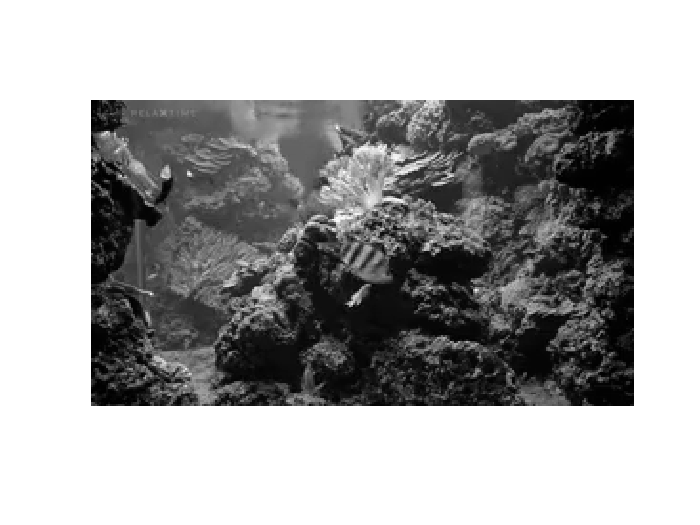

clear
close all
load myposnegmapblk.txt

savevideo=0;
showvdo = 0;

boxColor = [1,1,0];

% video file name
filename='coralreefht.mp4';
% get video information
vidObj = VideoReader(filename);
nt = vidObj.NumFrames;
nx = vidObj.Width;
ny = vidObj.Height;
fr = vidObj.FrameRate;
% convert video to grayscale and equalize
videoRGB = read(vidObj,[1 nt]);
I=zeros([ny,nx,nt]);
for t=1:nt
    I(:,:,t)=(rgb2gray(videoRGB(:,:,:,t)));%histeq
end
%clear videoRGB
clear vidObj
figure; % display video frames

if showvdo == 1
    for t=1:nt
        imagesc(I(:,:,t))
        colormap(gray), axis image, axis off
        title(['Frame ',num2str(t)])
        pause(.1)
    end
end

figure;
imagesc(I(:,:,16))
colormap(gray), axis image, axis off

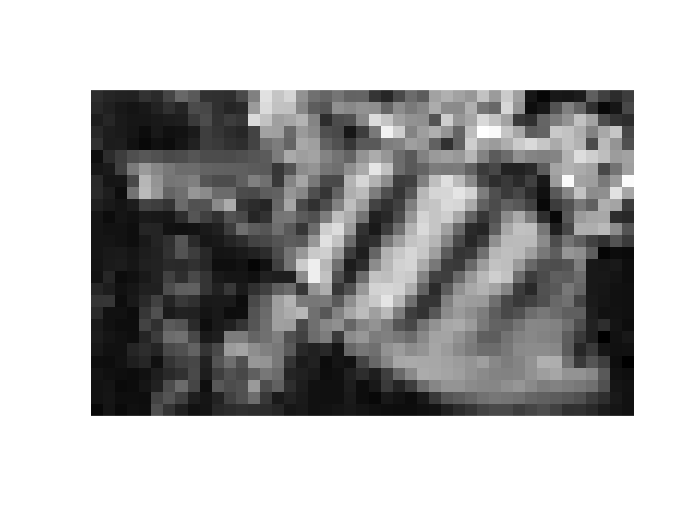


% extract and form template
tw = 26;
tl = 44;
zfish=squeeze(I(70:70+tw,116:116+tl,16));
figure;
imagesc(zfish)
colormap(gray), axis image, axis off

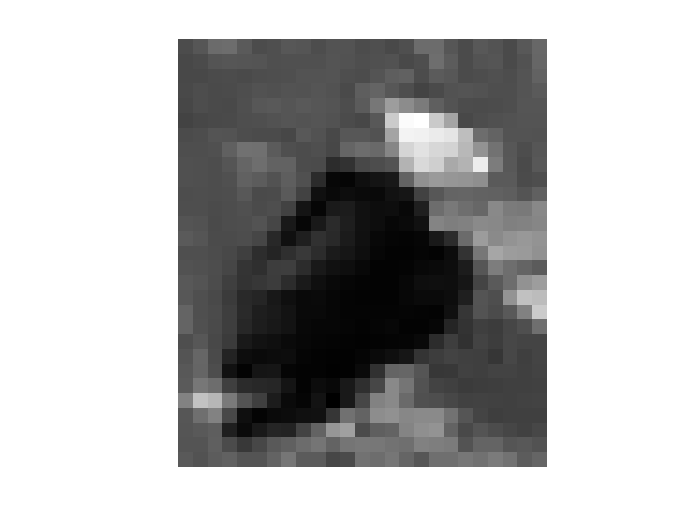


% extract and form template
tw = 28;
tl = 24;
bwfish=squeeze(I(40:40+tw,40:40+tl,71));
figure;
imagesc(bwfish)
colormap(gray), axis image, axis off

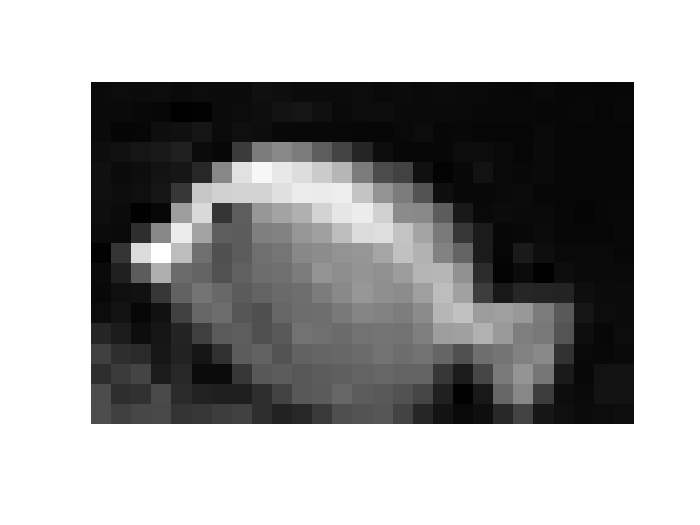


% extract and form template
tw = 16;
tl = 26;
wfish=squeeze(I(112:112+tw,125:125+tl,129));
figure;
imagesc(wfish)
colormap(gray), axis image, axis off

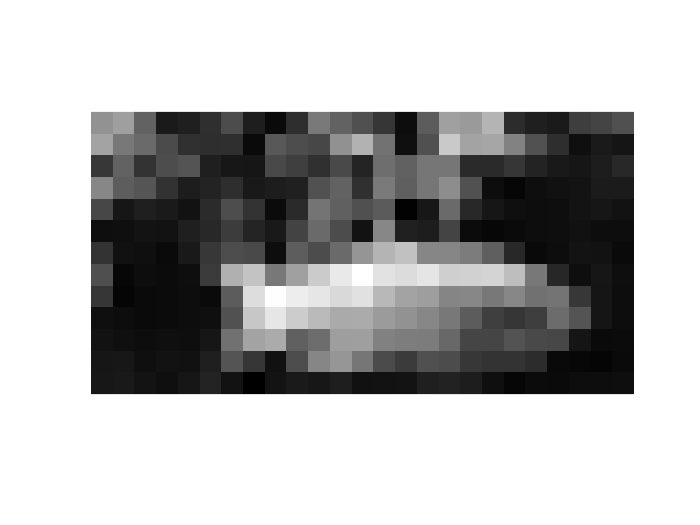



% extract and form template
tw = 12;
tl = 24;
smfish=squeeze(I(80:80+tw,140:140+tl,193));
figure;
imagesc(smfish)
colormap(gray), axis image, axis off


% Tempate FFT based correlation 
[smSx, smVarx, smftt1fill, smfttfill] = fftTemplatePre(smfish, ny, nx);

[zSx, zVarx, zftt1fill, zfttfill]     = fftTemplatePre(zfish, ny, nx);

[wSx, wVarx, wftt1fill, wfttfill]     = fftTemplatePre(wfish, ny, nx);

[bwSx, bwVarx, bwftt1fill, bwfttfill] = fftTemplatePre(bwfish, ny, nx);

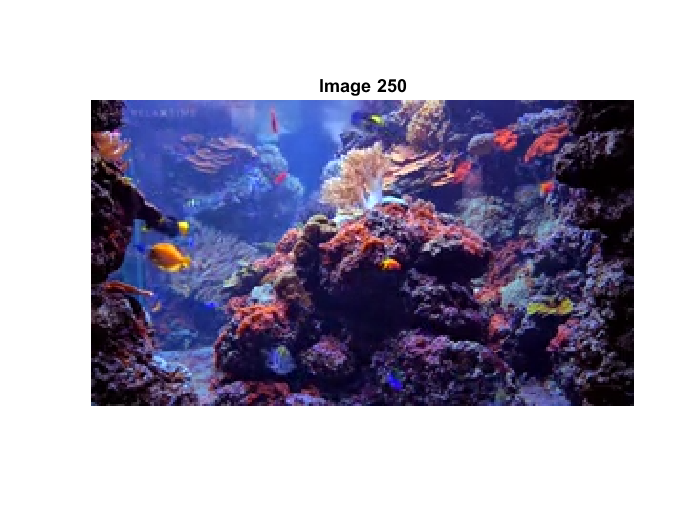

% track through all images
Corxy=zeros(ny,nx,nt);
figure;
%pause
tsm = 0;
tbw = 0;
tw  = 0;


for t=1:nt
    [tsm, indxsm, indysm, flagsm] = fftTemplateMatch(I(:,:,t), smfish, smSx, smVarx, smfttfill, smftt1fill, [1,0,0], tsm);
    [tbw, indxbw, indybw, flagbw] = fftTemplateMatch(I(:,:,t), bwfish, bwSx, bwVarx, bwfttfill, bwftt1fill, [1,1,0], tbw);
    [tw, indxw, indyw, flagw]     = fftTemplateMatch(I(:,:,t), wfish,  wSx,  wVarx,  wfttfill,  wftt1fill,  [1,0,1], tw);
    pause(.000001)
    
    imagesc(videoRGB(:,:,:,t))
    axis image, axis off
    title(['Image ',num2str(t)])
end